addpath 'Exp Data'
clc
clear all;

# Term Project Report

## Modelling

This section will deal with modelling the pendulum servo system under consideration.

### Determination of System Parameters from Experimental Data

First, the experimental data is imported and the values of system constants $K_m, ~K_t, ~K_p, $ and $K_a$ are determined using various techniques.  The data is found in the "SS_speeds_voltages_data.xlsx" excel spreadsheet located in the "Exp Data" repository sub-folder. The parameters are defined as follows:


$$\begin{array}{rl}

K_m

&= ~\frac{ \omega_{ss}}{v_m} \\

K_t

&= ~\frac{v_t}{ \omega}\\

K_p

&= ~\frac{v_p}{ \theta_o}\\

K_a

&= ~\frac{v_m}{v_o}



\end{array}$$


$K_m$ is the motor speed constant (which is related to additional motor parameters below),  the tachometer constant is $K_t$, the potentiometer constant is$K_p$, and the inverting power amplifier constant is $K_a$. The variable $\omega_{ss}$ is the motor's steady state angular velocity reached when a step input voltage of $v_m$ is applied. The voltage $v_t$ is an output of the tachometer for any given, instantanous motor angular velocity $\omega$. For the position constant, the voltage $v_p$ represents the potentiometer voltage reading given gear reduced ouput angle $\theta_o$. This output angle is related to the motor shaft angle through gear ratio $N$: 

$\theta_o = \frac{\theta_m}{N}$.

In addition to these parameters, the motor-with-gearbox open loop time constant $\tau_m$ must be determined from step response data provided. This, along with $K_m$ (also determined experimentally) will provide for almost all of the relationships that will be needed to model the motor within the system. Their equations are:


$$\tau_m ~=~ \frac{J_m}{K_{fm} + \frac{K_c}{R_a}K_b}$$


and 


$$K_m ~=~ \frac{ \frac{K_c}{R_a}}{K_{fm} + \frac{K_c}{R_a}K_b}$$


Where $K_{fm}$ is the motor's viscous damping coefficient, $R_a$ is its armature resistance, $K_c$ is its torque/current constant, $K_b$ is its back emf constant, and $J_m$ is the combined mass moment of inertia of the motor armature and the gearbox. 

One more experimental measurement is required - the ratio $ \frac{K_c}{R_a}$ can be ascertained from the static torque required to move the pendulum from equilibrium when it is at -90 degrees (horizontal). This static torque-voltage constant is found from: 


$$ \frac{K_c}{R_a} ~=~ \frac{MgL}{v_{m,0}}$$


where $M$is the mass of the pendulum bob, $g$ is the gravitational constant, and $L$ is the moment arm from the pendulum's point of rotation to the pendulum bob. 

%%Set up the Import Options and Import the Steady State Speed vs. Voltage Data

%This portion of code was generated automatically in MATLAB using the "Import Data" tool 
%and its "Generate Script" functionality. The file path for the readtable function call 
% has been modified to work with the file system scheme used in this report. Additionally, 
% the data originally output as an array is transfered into the struct "SS_w_v_dat". 

opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A3:D13";

% Specify column names and types
opts.VariableNames = ["MotorSpeed", "Vo", "Vm", "VT"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Import the data
SSspeedsvoltagesdata = readtable("F:\Sourcetree Repos\Matlab Personal\EE 514\Term Project\Exp Data\SS_speeds_voltages_data.xlsx", opts, "UseExcel", false);

%%Convert to output type to an array and then fill a struct with the data 
SSspeedsvoltagesdata = table2array(SSspeedsvoltagesdata);
SS_w_v_dat.MotorSpeed = SSspeedsvoltagesdata(:,1);
SS_w_v_dat.Vo = SSspeedsvoltagesdata(:,2);
SS_w_v_dat.Vm = SSspeedsvoltagesdata(:,3);
SS_w_v_dat.Vt = SSspeedsvoltagesdata(:,4);

%%Clear temporary variables
clear opts SSspeedsvoltagesdata

%%Sort the Data By Increasing Values of Motor Speed
[MotorSpeed, I] = sort(SS_w_v_dat.MotorSpeed);
SS_w_v_dat.MotorSpeed = MotorSpeed;
SS_w_v_dat.Vm = SS_w_v_dat.Vm(I);
SS_w_v_dat.Vt = SS_w_v_dat.Vt(I);
SS_w_v_dat.Vo = SS_w_v_dat.Vo(I);
clear MotorSpeed


%%Set up the Import Options and Import the Position Sensor Data

%This portion of code was generated automatically in MATLAB using the "Import Data" tool 
%and its "Generate Script" functionality. The file path for the readtable function call 
% has been modified to work with the file system scheme used in this report. 

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel2V", "Math1V"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
PositionSensor = readtable("\Exp Data\PositionSensor.csv", opts);

%% Convert to output type
PositionSensor = table2array(PositionSensor);

%% Clear temporary variables
clear opts

%%Set up the Import Options and Import the Step Response 1 Data

%This portion of code was generated automatically in MATLAB using the "Import Data" tool 
%and its "Generate Script" functionality. The file path for the readtable function call 
% has been modified to work with the file system scheme used in this report. 

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel2V", "Math1V"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Step1 = readtable("\Exp Data\Step1.csv", opts);

%% Convert to output type
Step1 = table2array(Step1);

%% Clear temporary variables
clear opts



%%Set up the Import Options and Import the Step Response 2 Data

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel2V", "Math1V"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Step2 = readtable("\Exp Data\Step2.csv", opts);

%% Convert to output type
Step2 = table2array(Step2);

%% Clear temporary variables
clear opts



%%Set up the Import Options and Import the Step Response 3 Data

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel2V", "Math1V"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Step3 = readtable("\Exp Data\Step3.csv", opts);

%% Convert to output type
Step3 = table2array(Step3);

%% Clear temporary variables
clear opts

#### Determine the Motor Speed Constant and the Breakaway Voltage

BA_index = SS_w_v_dat.MotorSpeed == 0; %Datapoints before the breakaway voltage is reached

$K_m $ is determined from the slope of a linear curve fit to the non-zero data points.

Km_fit = polyfit(SS_w_v_dat.Vm(~BA_index),SS_w_v_dat.MotorSpeed(~BA_index),1);
fprintf(['Km is found to be ' num2str(round(Km_fit(1),1)) ' [RPM/V]'])

Km is found to be 220.9 [RPM/V]

Breakaway voltage, $v_{ba}$, is determined by finding x intercept of the linear curve fit to all non-zero voltage data points.

v_ba = -Km_fit(2)/Km_fit(1);
fprintf(['Breakaway voltage is found to be ' num2str(v_ba) ' [V]'])

Breakaway voltage is found to be 1.0684 [V]

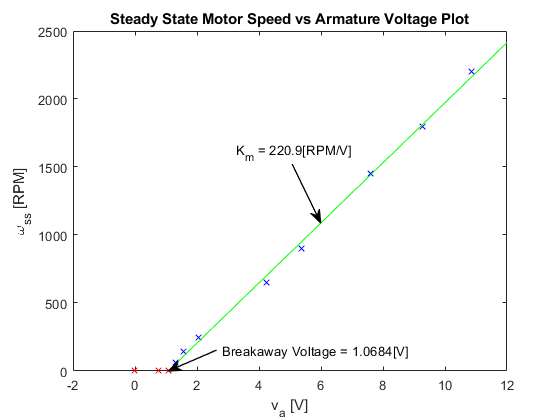


plot(SS_w_v_dat.Vm(BA_index),SS_w_v_dat.MotorSpeed(BA_index), 'r x',SS_w_v_dat.Vm(~BA_index),SS_w_v_dat.MotorSpeed(~BA_index), 'b x', [v_ba 12],[0 Km_fit(1)*12 + Km_fit(2)],'g')
xlabel('v_a [V]')
ylabel('\omega_{ss} [RPM]')
title('Steady State Motor Speed vs Armature Voltage Plot')

%Breakaway Location Annotation
ax = gca;
LArr = .1; %Length of Arrow
PhiArr = deg2rad(30);
%Arrow Head
[xh, yh] = ds2nfu(ax,SS_w_v_dat.Vm(length(SS_w_v_dat.Vm(BA_index))), 0);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['Breakaway Voltage = ' num2str(round(v_ba,4)) '[V]'],'FontSize',10,'Linewidth',1)

%Slope Annotation
ax = gca;
LArr = .15; %Length of Arrow
PhiArr = deg2rad(110);
%Arrow Head
[xh, yh] = ds2nfu(ax,6, Km_fit(1)*6 + Km_fit(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['K_m = ' num2str(round(Km_fit(1),1)) '[RPM/V]'],'FontSize',10,'Linewidth',1)

#### Determine the Tachometer Constant

A linear curve fit is used to approximate the tachometer measurement constant $K_t = \frac{v_t}{\omega}$  from experimental data. 

Kt_fit = polyfit(SS_w_v_dat.MotorSpeed,SS_w_v_dat.Vt,1);
fprintf(['Kt is found to be ' num2str(round(Kt_fit(1),3)) ' [V/RPM]'])

Kt is found to be -0.015 [V/RPM]

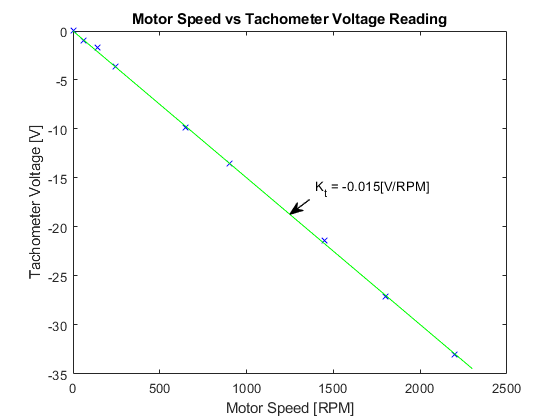


plot(SS_w_v_dat.MotorSpeed,SS_w_v_dat.Vt, 'b x',[0 2300],[0 Kt_fit(1)*2300 + Kt_fit(2)],'g' )
xlabel('Motor Speed [RPM]')
ylabel('Tachometer Voltage [V]')
title('Motor Speed vs Tachometer Voltage Reading')

%Slope Annotation
ax = gca;
LArr = .05; %Length of Arrow
PhiArr = deg2rad(45);
%Arrow Head
[xh, yh] = ds2nfu(ax,1250, Kt_fit(1)*1250 + Kt_fit(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['K_t = ' num2str(round(Kt_fit(1),3)) '[V/RPM]'],'FontSize',10,'Linewidth',1)

#### Determine the Inverting Power Amplifier Constant

A linear curve fit is used to approximate the tachometer measurement constant $K_a = ~\frac{v_m}{v_o}$  from experimental data. 

Ka_fit = polyfit(SS_w_v_dat.Vo,SS_w_v_dat.Vm,1);
fprintf(['Kt is found to be ' num2str(Ka_fit(1)) ' [V/V]'])

Kt is found to be -5.0204 [V/V]

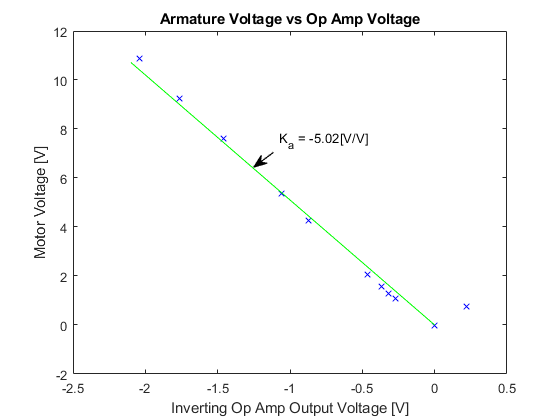


plot(SS_w_v_dat.Vo,SS_w_v_dat.Vm, 'b x',[0 -2.1],[0 Ka_fit(1)*-2.1 + Ka_fit(2)],'g' )
xlabel('Inverting Op Amp Output Voltage [V]')
ylabel('Motor Voltage [V]')
title('Armature Voltage vs Op Amp Voltage')

%Slope Annotation
ax = gca;
LArr = .05; %Length of Arrow
PhiArr = deg2rad(45);
%Arrow Head
[xh, yh] = ds2nfu(ax,-1.25, Ka_fit(1)*-1.25 + Ka_fit(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['K_a = ' num2str(round(Ka_fit(1),3)) '[V/V]'],'FontSize',10,'Linewidth',1)

#### Determine the Potentiometer Constant

Data is separated (roughly) by linear regions of the sawtooth wave and a linear curve fit is given to each. The slopes are then averaged to determine a value in volts per second.

I_p_1 = ((.15 < PositionSensor(:,1)) & (PositionSensor(:,1) < .55));
I_p_2 = ((.63 < PositionSensor(:,1)) & (PositionSensor(:,1) < 1.1));
I_p_3 = ((1.25 < PositionSensor(:,1)) & (PositionSensor(:,1) < 1.75));

m_fit1 = polyfit(PositionSensor(I_p_1,1),PositionSensor(I_p_1,3),1);
fprintf(['First slope fit is ' num2str(m_fit1(1)) ' [V/s]'])

First slope fit is 52.207 [V/s]


m_fit2 = polyfit(PositionSensor(I_p_2,1),PositionSensor(I_p_2,3),1);
fprintf(['Second slope fit is ' num2str(m_fit2(1)) ' [V/s]'])

Second slope fit is 52.496 [V/s]


m_fit3 = polyfit(PositionSensor(I_p_3,1),PositionSensor(I_p_3,3),1);
fprintf(['Third slope fit is ' num2str(m_fit3(1)) ' [V/s]'])

Third slope fit is 52.6473 [V/s]

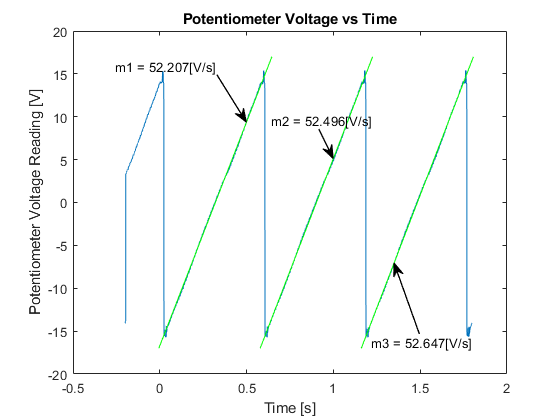


plot(PositionSensor(:,1),PositionSensor(:,3),'-',[(-17 - m_fit1(2))/m_fit1(1)  (17 - m_fit1(2))/m_fit1(1)],[-17 17],'g',...
    [(-17 - m_fit2(2))/m_fit2(1)  (17 - m_fit2(2))/m_fit2(1)],[-17 17],'g' ,[(-17 - m_fit3(2))/m_fit3(1)  (17 - m_fit3(2))/m_fit3(1)],[-17 17],'g'  )
xlabel('Time [s]')
ylabel('Potentiometer Voltage Reading [V]')
title('Potentiometer Voltage vs Time')

%Slope Annotations
ax = gca;

% m_fit1
LArr = .125; %Length of Arrow
PhiArr = deg2rad(115);
%Arrow Head
[xh, yh] = ds2nfu(ax,.5, m_fit1(1)*.5 + m_fit1(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['m1 = ' num2str(round(m_fit1(1),3)) '[V/s]'],'FontSize',10,'Linewidth',1)

% m_fit2
LArr = .075; %Length of Arrow
PhiArr = deg2rad(110);
%Arrow Head
[xh, yh] = ds2nfu(ax,1, m_fit2(1)*1 + m_fit2(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['m2 = ' num2str(round(m_fit2(1),3)) '[V/s]'],'FontSize',10,'Linewidth',1)

% m_fit3
LArr = .175; %Length of Arrow
PhiArr = deg2rad(-75);
%Arrow Head
[xh, yh] = ds2nfu(ax,1.35, m_fit3(1)*1.35 + m_fit3(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['m3 = ' num2str(round(m_fit3(1),3)) '[V/s]'],'FontSize',10,'Linewidth',1)

The period of the sawtooth waveform is found by manually finding the timespan associated with the initial and final positive peak of the data and dividing that by three.


$$T_p = \frac{t_{peak3} - t_{peak0}}{3}$$


Using the average of the slopes determined from the three linear curve fits above, $K_p$ is computed.


$$K_p = \frac{2\pi *avg(m_{fit1},~m_{fit2},~m_{fit3})}{T_p}$$


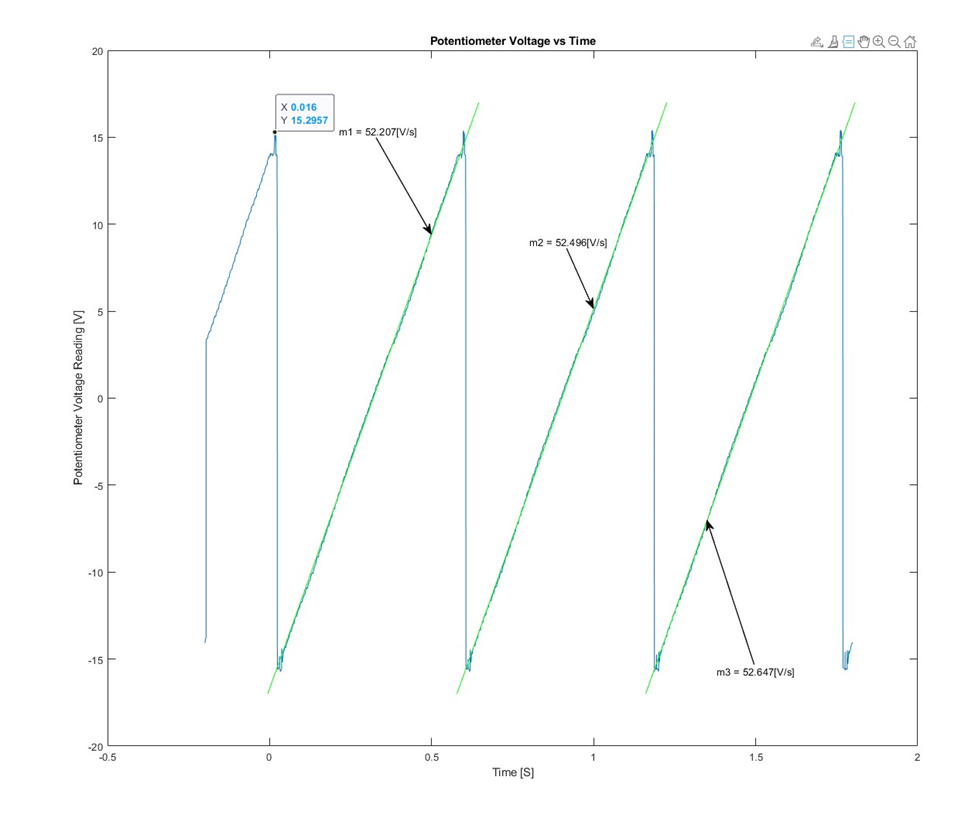

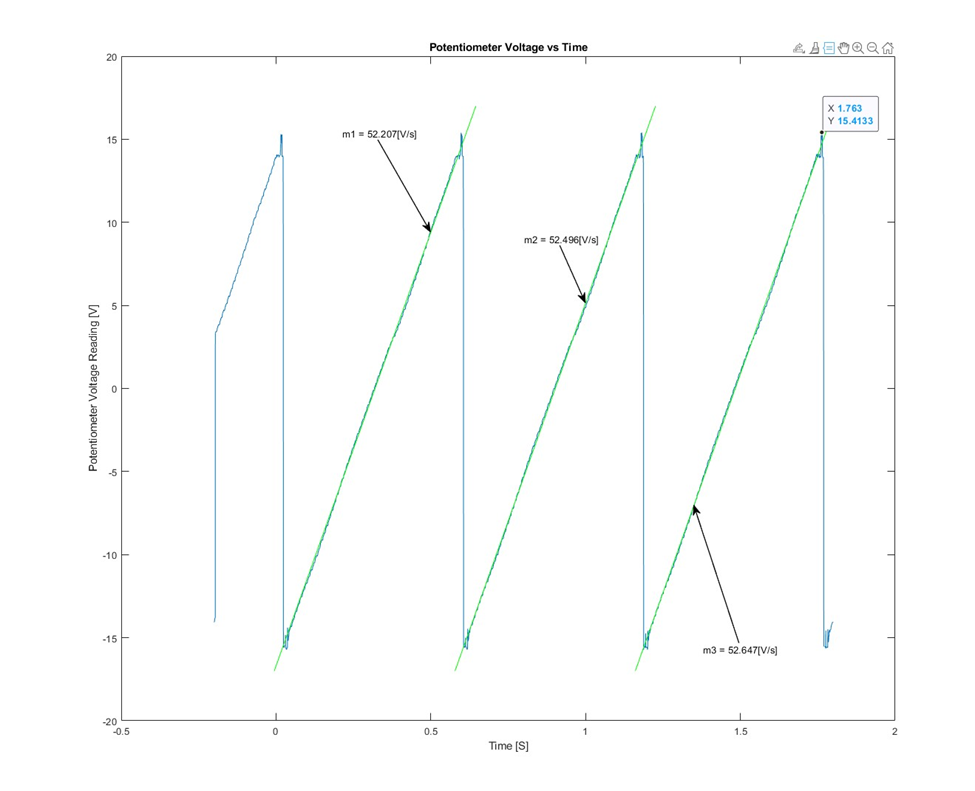

period_st_wave = (1.763 - 0.016)/3;
fprintf(['T_p is found to be ' num2str(round(period_st_wave,3)) ' [sec]'])

T_p is found to be 0.582 [sec]


Kp = -mean([m_fit1(1) m_fit2(1) m_fit3(1)])*period_st_wave/(2*pi);
fprintf(['K_p is found to be ' num2str(round(Kp,1)) ' [V/rad]'])

K_p is found to be -4.9 [V/rad]

The $K_p$ value is slightly less than the expected value of 30 one gets from visually inspecting the data. This is because there is a deadzone nonlinearity present in the potentiometer that occurs right around the rollover point. 

#### Determine the Motor Time Constant

First, an estimate of the steady state voltage is found by averaging a range of values near the end of the data collected for each step response. The final one percent of the data points are used for each calculation. 

Index_i_1 = length(Step1(:,1)) - round(length(Step1(:,1))/100);
v_ss_1 = mean(Step1(Index_i_1:end,3));
fprintf(['Steady state tachometer reading 1 is found to be ' num2str(round(v_ss_1,3)) ' [Volts]'])

Steady state tachometer reading 1 is found to be 23.364 [Volts]

Index_i_2 = length(Step2(:,1)) - round(length(Step2(:,1))/10);
v_ss_2 = mean(Step2(Index_i_2:end,3));
fprintf(['Steady state tachometer reading 2 is found to be ' num2str(round(v_ss_2,3)) ' [Volts]'])

Steady state tachometer reading 2 is found to be 25.08 [Volts]

Index_i_3 = length(Step3(:,1)) - round(length(Step3(:,1))/10);
v_ss_3 = mean(Step3(Index_i_3:end,3));
fprintf(['Steady state tachometer reading 3 is found to be ' num2str(round(v_ss_3,3)) ' [Volts]'])

Steady state tachometer reading 3 is found to be 14.114 [Volts]

To better estimate the time constant, a 100 point moving mean is used to attempt to smooth out the data in the transient regions. This is shown in red and overlays the raw data plotted below. 

k = 100;
%Step response 1 smoothed
Step1_movmean = movmean(Step1(:,3),k);
t_Step1_movmean = linspace(Step1(1,1), Step1(end,1), length(Step1(:,1))).';
%Step response 2 smoothed
Step2_movmean = movmean(Step2(:,3),k);
t_Step2_movmean = linspace(Step2(1,1), Step2(end,1), length(Step2(:,1))).';
%Step response 3 smoothed
Step3_movmean = movmean(Step3(:,3),k);
t_Step3_movmean = linspace(Step3(1,1), Step3(end,1), length(Step3(:,1))).';

Next, the first voltage to exceed 63.21% of the step response's steady state voltage is found from the *averaged *data, not the raw data. Its associated time is taken to be the time constant for the response.

mask_tau1 = Step1_movmean <= v_ss_1*.6321;
[v_tau1, I_tau1] = max(Step1(mask_tau1,3));
tau1 = Step1(I_tau1,1);
fprintf(['Time constant for step response 1 is found to be ' num2str(tau1) ' [s]'])

Time constant for step response 1 is found to be 0.28634 [s]


mask_tau2 = Step2_movmean <= v_ss_2*.6321;
[v_tau2, I_tau2] = max(Step2(mask_tau2,3));
tau2 = Step2(I_tau2,1);
fprintf(['Time constant for step response 2 is found to be ' num2str(tau2) ' [s]'])

Time constant for step response 2 is found to be 0.27318 [s]


mask_tau3 = Step3_movmean <= v_ss_3*.6321;
[v_tau3, I_tau3] = max(Step3(mask_tau3,3));
tau3 = Step3(I_tau3,1);
fprintf(['Time constant for step response 3 is found to be ' num2str(tau3) ' [s]'])

Time constant for step response 3 is found to be 0.25984 [s]

Finally, the motor's time constant is taken to be the average of these three values

tau = mean([tau1 tau2 tau3]);
fprintf(['The motor time constant is found to be ' num2str(round(tau,3)) ' [s]'])

The motor time constant is found to be 0.273 [s]

Finally, results are plotted with raw data, smoothed data, steady state voltage value, and associated time constants overlayed. 

**Plot Step Response 1:**

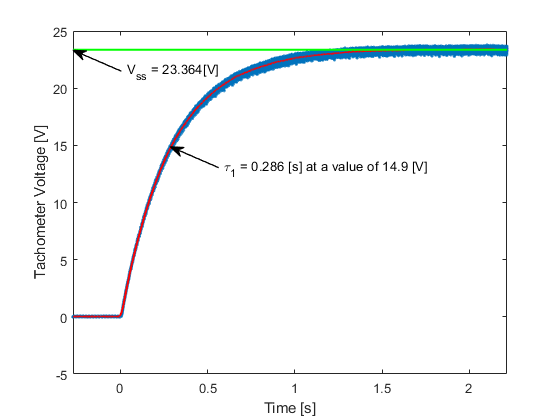

plot(Step1(:,1), Step1(:,3), '.',t_Step1_movmean,Step1_movmean, 'r', [min(Step1(:,1)) max(Step1(:,1))],[v_ss_1 v_ss_1], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
xlim([min(Step1(:,1)) max(Step1(:,1))])

%Annotations
ax = gca;

% Steady State Voltage 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax,min(Step1(:,1)), v_ss_1);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['V_{ss} = ' num2str(round(v_ss_1,3)) '[V]'],'FontSize',10,'Linewidth',1)

% Time constant 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax, tau1,v_tau1);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['\tau_1 = ' num2str(round(tau1,3)) ' [s] at a value of ' num2str(round(v_tau1, 1)) ' [V]'],'FontSize',10,'Linewidth',1)

**Plot Step Response 2:**

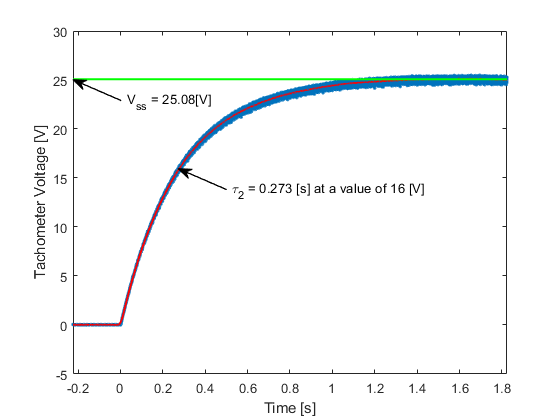

plot(Step2(:,1), Step2(:,3), '.',t_Step2_movmean,Step2_movmean, 'r', [min(Step2(:,1)) max(Step2(:,1))],[v_ss_2 v_ss_2], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
xlim([min(Step2(:,1)) max(Step2(:,1))])

%Annotations
ax = gca;

% Steady State Voltage 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax,min(Step2(:,1)), v_ss_2);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['V_{ss} = ' num2str(round(v_ss_2,3)) '[V]'],'FontSize',10,'Linewidth',1)

% Time constant 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax, tau2,v_tau2);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['\tau_2 = ' num2str(round(tau2,3)) ' [s] at a value of ' num2str(round(v_tau2, 1)) ' [V]'],'FontSize',10,'Linewidth',1)

**Plot Step Response 3:**

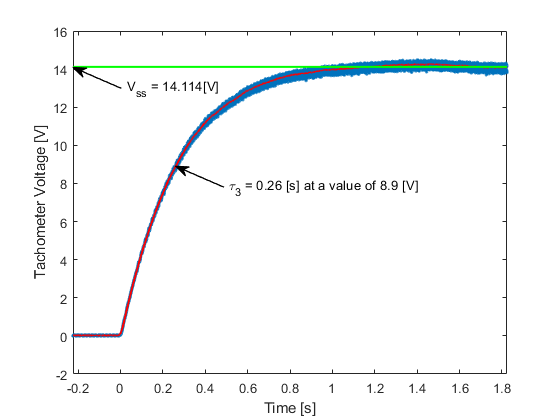

plot(Step3(:,1), Step3(:,3), '.',t_Step3_movmean,Step3_movmean, 'r', [min(Step3(:,1)) max(Step3(:,1))],[v_ss_3 v_ss_3], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
xlim([min(Step3(:,1)) max(Step3(:,1))])

%Annotations
ax = gca;

% Steady State Voltage 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax,min(Step3(:,1)), v_ss_3);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['V_{ss} = ' num2str(round(v_ss_3,3)) '[V]'],'FontSize',10,'Linewidth',1)

% Time constant 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax, tau3,v_tau3);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['\tau_3 = ' num2str(round(tau3,3)) ' [s] at a value of ' num2str(round(v_tau3, 1)) ' [V]'],'FontSize',10,'Linewidth',1)

#### Determine the Static Torque Voltage Constant $\frac{K_c}{R_a}$


$$ \frac{K_c}{R_a}~ =~ \frac{MgL}{v_{m,0}}$$


Where


$$M = 0.028~ [kg]$$



$$L = 0.0254~[m]$$



$$g = 9.81 ~[\frac{m}{s^2}]$$



$$v_{m,0} = 0.66~[V]$$


M_n = 28e-3; %[kg]
L_n = 11*.0254; %[m]
g_n = 9.81; %[m/s^2]
vm0 = 0.66; %[V]

KcRa = M_n*g_n*L_n/vm0;
fprintf(['The static torque voltage constant is found to be ' num2str(round(KcRa,4)) ' [Nm/V]'])

The static torque voltage constant is found to be 0.1163 [Nm/V]

#### Determine the Torque Required to Break Through the Static Friction in the Step Responses

The motor circuit is modelled as follows.

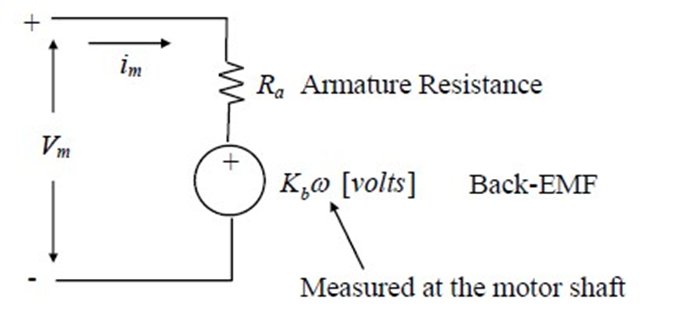

In the static friction case, when the motor is stalled, no $\omega$ has developed in the system and all the electrical power is being dissipated as heat through $R_a$. The armature KVL in this scenario is simply


$$v_m = i_mR_a$$


The torque produced by a DC motor is given by 


$$T_m = K_ci_m$$


Therefore, 


$$T_m ~=~ \frac{K_c}{R_a}v_m$$


The torque required to break the system out stall, $T_{ba}$, is related to the breakaway voltage, $v_{ba}$, from the $\omega_{ss}$ vs $v_a$ dataset through the stalled motor condition. At the tipping point


$$T_{ba} ~=~ \frac{K_c}{R_a}v_{ba}$$


There is an inherent assumption here that most of the static friction torque is lumped at the motor side of the speed reducer, not the pendulum side. In reality, there is a contribution to stiction from the individual mechanical elements of the reducer. Since it would be out of the scope of this report to determine what exactly is contributing to stiction and its consequence on the static force balance problem, this is an assumption that must be made. 

T_ba = KcRa*v_ba;c
fprintf(['The breakaway torque is found to be ' num2str(round(T_ba,4)) ' [Nm]'])

The breakaway torque is found to be 0.1242 [Nm]

#### Algebraically Determine the Remaining System Parameters 

First, convert constants to SI units

Km_n = Km_fit(1)*2*pi/60; %[(rad/s)/V]
fprintf(['The motor velocity constant Km is ' num2str(round(Km_n,3)) ' [rad/Vs]'])

The motor velocity constant Km is 23.133 [rad/Vs]

Kt_n = Kt_fit(1)*60/(2*pi); %[V/(rad/s)]
fprintf(['The tachometer constant Kt is ' num2str(round(Kt_n,3)) ' [Vs/rad]'])

The tachometer constant Kt is -0.143 [Vs/rad]

When the friction constant $K_{fm}$ is eliminated from the definitions of $\tau_m$ and $K_m$, the motor inertia has the relationship


$$J_m ~=~\frac{K_c}{R_a}\frac{\tau_m}{K_m}$$


Jm_n = KcRa*tau/Km_n;
fprintf(['The motor polor moment of inertia Jm is ' num2str(round(Jm_n,4)) ' [kg-m-s^2]'])

The motor polor moment of inertia Jm is 0.0014 [kg-m-s^2]

### Relating Found System Parameters to a Nonlinear Motorized Pendulum Model

A schematic representation of the motorized pendulum system is shown below. 

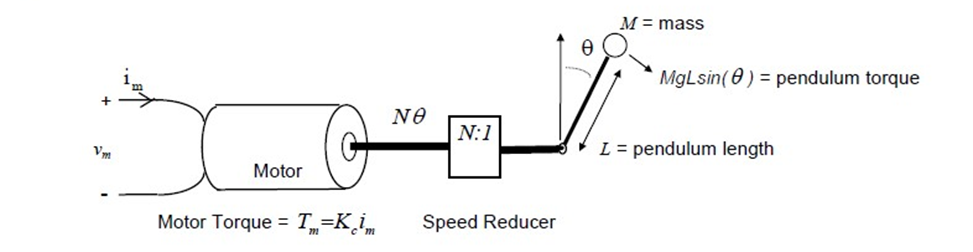

A nonlinear model of the pendulum kinetics is expressed in terms of an input armature voltage actuation as such:

syms K_c R_a v_m N J_m J_p theta_ddot K_fm K_b theta_dot M g L theta K_m


$$\frac{K_c }{R_a } \,v_m~=~\theta^˙ \,{\left(K_{\textrm{fm}} \,N+\frac{K_b \,K_c \,N}{R_a }\right)}+\theta^¨ \,{\left(J_m \,N+J_p \right)}-L\,M\,g\,\mathrm{sin}\left(\theta \right)$$


Where friction due to the pendulum itself is assumed to be negligible. The pendulum's moment of inertia, $J_p$, is given by


$$J_p ~=~ L^2M$$


Jp = L_n^2*M_n;

and $N = 8.1$ is a gear ratio between the motor shaft and the pendulum. The input to the system is voltage $v_m$, the motor's armature voltage - this can be related to our control actuation $v_o$ through $K_a$. This will have to be done for all of the measured states as well so that gain selecting resistors can be placed in the physical electronics. From rearranging the equation for $\tau_m$, the terms $K_{fm} + K_b\frac{K_c}{R_a}$ in the pendulum model can be eliminated in favor of known values. 


$$\tau_m ~=~ \frac{J_m}{K_{fm} + \frac{K_c}{R_a}K_b}$$



$$\frac{\tau_m}{J_m} ~=~ \frac{1}{K_{fm} + \frac{K_c}{R_a}K_b}$$



$$K_{fm} + K_b\frac{K_c}{R_a} ~=~ \frac{J_m}{\tau_m}$$


And from $J_m$ above


$$K_{fm} + K_b\frac{K_c}{R_a} ~=~ \frac{1}{K_m}\frac{K_c}{R_a}$$


Hence

PendulumEOM = K_c/R_a*v_m == (N*J_m + J_p)*theta_ddot + N*1/K_m*K_c/R_a*theta_dot - M*g*L*sin(theta);


$$\frac{K_c \,v_m }{R_a }=\theta^¨ \,{\left(J_m \,N+J_p \right)}-L\,M\,g\,\mathrm{sin}\left(\theta \right)+\frac{K_c \,N\,\theta^˙ }{K_m \,R_a }$$


### Nonlinear State Space Representation of the Motorized Pendulum

The full nonlinear state space representation is

NL_PendulumSS = [theta_dot;theta_ddot] == expand([theta_dot;rhs(isolate(PendulumEOM, theta_ddot))]);


$$\left\lbrack \begin{array}{c}

\theta^˙\\
\theta^¨ 

\end{array}\right\rbrack 

=

\left\lbrack \begin{array}{c}

\theta^˙\\

\frac{K_c \,v_m }{J_m \,N\,R_a +J_p \,R_a }-\frac{K_c \,N\,\theta^˙ }{J_m \,K_m \,N\,R_a +J_p \,K_m \,R_a }+\frac{L\,M\,g\,\mathrm{sin}\left(\theta \right)}{J_m \,N+J_p }

\end{array}\right\rbrack$$


Taking the Jacobian w.r.t the state yields

Jacobian = jacobian(rhs(NL_PendulumSS), [theta theta_dot]);


$$\left\lbrack \begin{array}{cc}
0 & 1\\
\frac{L\,M\,g\,\mathrm{cos}\left(\theta \right)}{J_m \,N+J_p } & -\frac{K_c \,N}{J_m \,K_m \,N\,R_a +J_p \,K_m \,R_a }
\end{array}\right\rbrack$$


and the input matrix is simply 

[B, extra] = equationsToMatrix(NL_PendulumSS, v_m);


$$\left\lbrack \begin{array}{c}
0\\
-\frac{K_c }{J_m \,N\,R_a +J_p \,R_a }
\end{array}\right\rbrack$$


%% Simulate the system
N_n = 8.1; %Gear ratio
